numFiles = 20;

addpath 'D:\dpl\MATLAB_Sim_and_Analysis' % Solver location
addpath 'D:\bearing_dpl\padeborn_dataset'% Dataset location
warning('off','all')

or_pd = zeros(1, numFiles*4);
ir_pd = zeros(1, numFiles*4);
h_pd = zeros(1, numFiles*4);

% FHN parameters
alpha = 10;
beta = 1;
w = 2400;

% From dataset documentation
originalFs = 64e+3; % [Hz]

% Resample to
targetFs = 16e+3; % [Hz]

% Solver setup & init con
[ab, bb, cb] = ButcherTableau.get("RK6");
solver = rk_solver(ab, bb, cb);

y01 = [0.2; 0.2];
tmax = 1;

fileGroups = {
    'N09_M07_F10_K001_', 'N09_M07_F10_KA01_', 'N09_M07_F10_KI07_';
    'N15_M01_F10_K001_', 'N15_M01_F10_KA01_', 'N15_M01_F10_KI07_';
    'N15_M07_F04_K001_', 'N15_M07_F04_KA01_', 'N15_M07_F04_KI07_';
    'N15_M07_F10_K001_', 'N15_M07_F10_KA01_', 'N15_M07_F10_KI07_'};

tic
for groupIdx = 1:1%size(fileGroups, 1)
    for i = 1:20 %numFiles
        % Load dataset data
        h_name = sprintf('%s%d.mat', fileGroups{groupIdx, 1}, i);
        ir_name = sprintf('%s%d.mat', fileGroups{groupIdx, 2}, i);
        or_name = sprintf('%s%d.mat', fileGroups{groupIdx, 3}, i);

        var_h_name = sprintf('%s%d', fileGroups{groupIdx, 1}, i);
        var_ir_name = sprintf('%s%d', fileGroups{groupIdx, 2}, i);
        var_or_name = sprintf('%s%d', fileGroups{groupIdx, 3}, i);

        load(h_name);
        load(ir_name);
        load(or_name);

        t_h = eval([var_h_name '.X(2).Data']);
        t_ir = eval([var_ir_name '.X(2).Data']);
        t_or = eval([var_or_name '.X(2).Data']);

        sig_h = eval([var_h_name '.Y(7).Data']);
        sig_ir = eval([var_ir_name '.Y(7).Data']);
        sig_or = eval([var_or_name '.Y(7).Data']);
        
        % Resample
        [p, q] = rat(targetFs / originalFs);
        [sig_h, t_h] = resample(sig_h, t_h, targetFs, p, q, 'pchip');
        [sig_ir, t_ir] = resample(sig_ir, t_ir, targetFs, p, q, 'pchip');
        [sig_or, t_or] = resample(sig_or, t_or, targetFs, p, q, 'pchip');
        
        % Trim
        [t_h, sig_h] = trim_signal(t_h, sig_h, targetFs, tmax);
        [t_ir, sig_ir] = trim_signal(t_ir, sig_ir, targetFs, tmax);
        [t_or, sig_or] = trim_signal(t_or, sig_or, targetFs, tmax);

        %Amp normalize
        sig_h = sig_h./rms(sig_h);
        sig_ir = sig_ir./rms(sig_ir);
        sig_or = sig_or./rms(sig_or);
        
        % Define FHN with external signal
        fhn_ir = @(t_ir, y) FHN_EXT(t_ir, y, w, alpha, beta, sig_ir, 1/targetFs);
        fhn_or = @(t_or, y) FHN_EXT(t_or, y, w, alpha, beta, sig_or, 1/targetFs);
        fhn_h = @(t_h, y) FHN_EXT(t_h, y, w, alpha, beta, sig_h,   1/targetFs);
        
        % Solve
        [ts_ir, sol_ir] = solver.solve(fhn_ir, t_ir(end), y01, 1/targetFs);
        [ts_or, sol_or] = solver.solve(fhn_or, t_or(end), y01, 1/targetFs);
        [ts_h, sol_h] = solver.solve(fhn_h, t_h(end), y01, 1/targetFs);
        
        % Compute peaks
        idx = (groupIdx-1)*size(fileGroups, 1) + i;
        [~, locs] = findpeaks(sol_or(1, :), "MinPeakHeight", 0.8, "MinPeakProminence", 0.1);
        or_pd(idx) = mean(diff(locs));
        [~, locs] = findpeaks(sol_ir(1, :), "MinPeakHeight", 0.8, "MinPeakProminence", 0.1);
        ir_pd(idx) = mean(diff(locs));
        [~, locs] = findpeaks(sol_h(1, :), "MinPeakHeight", 0.8, "MinPeakProminence", 0.1);
        h_pd(idx) = mean(diff(locs));

        clear(var_h_name);
        clear(var_or_name);
        clear(var_ir_name);
    end
end
toc

Elapsed time is 113.405026 seconds.


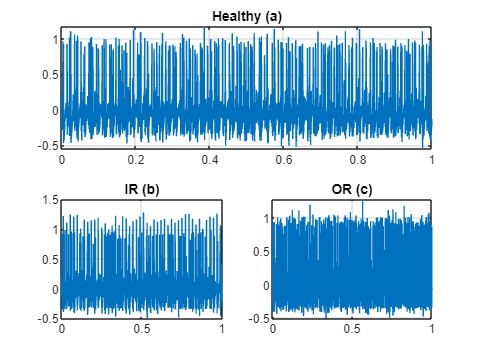


figure
subplot(2, 2, [1, 2])
plot(ts_h, sol_h(1, :));
grid on
title("Healthy (a)")
subplot(2, 2, 3)
plot(ts_ir, sol_ir(1, :));
grid on
title("IR (b)")
subplot(2, 2, 4)
plot(ts_or, sol_or(1, :));
grid on
title("OR (c)")

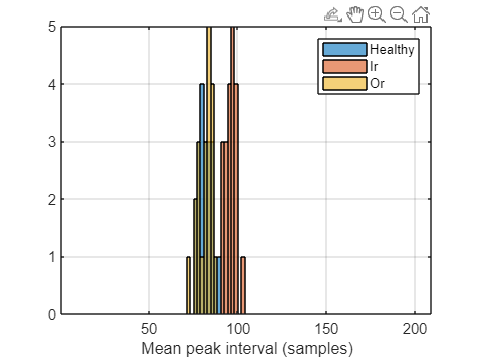


edges = linspace(10, 200, 100);
figure
histogram(h_pd, edges);
hold on
histogram(ir_pd, edges);
histogram(or_pd, edges);
xlabel("Mean peak interval (samples)")
legend("Healthy", "Ir", "Or")
grid on